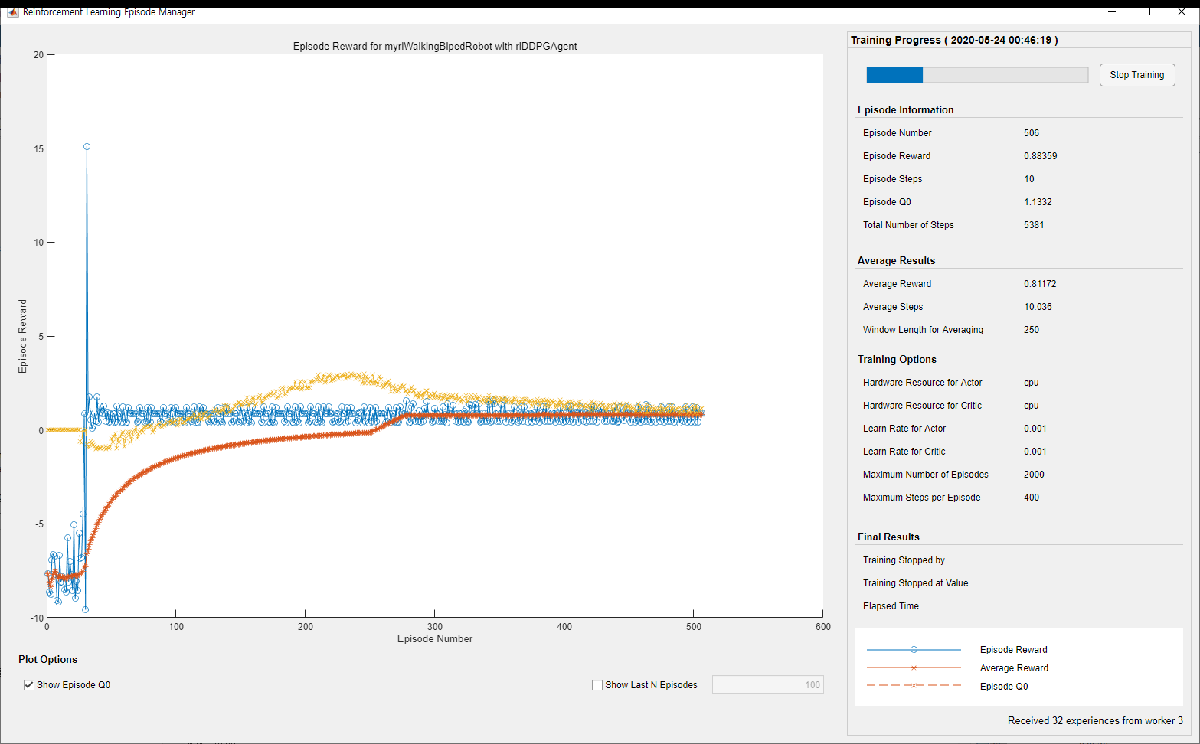

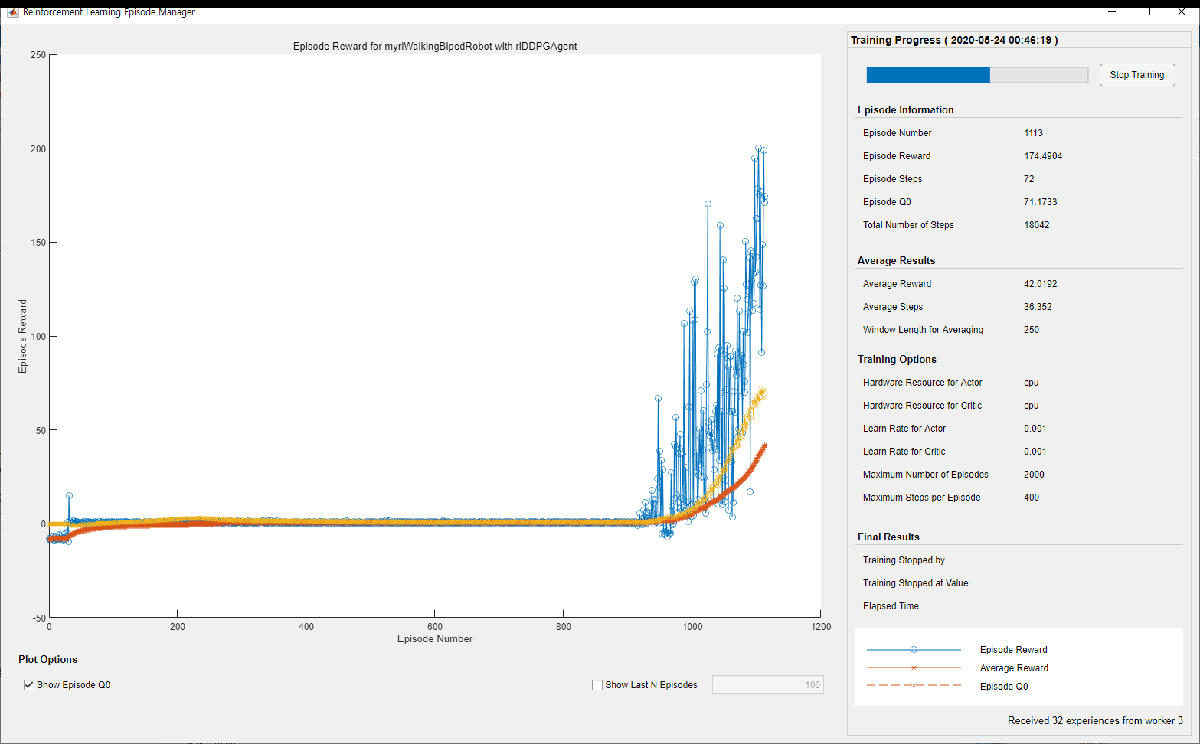

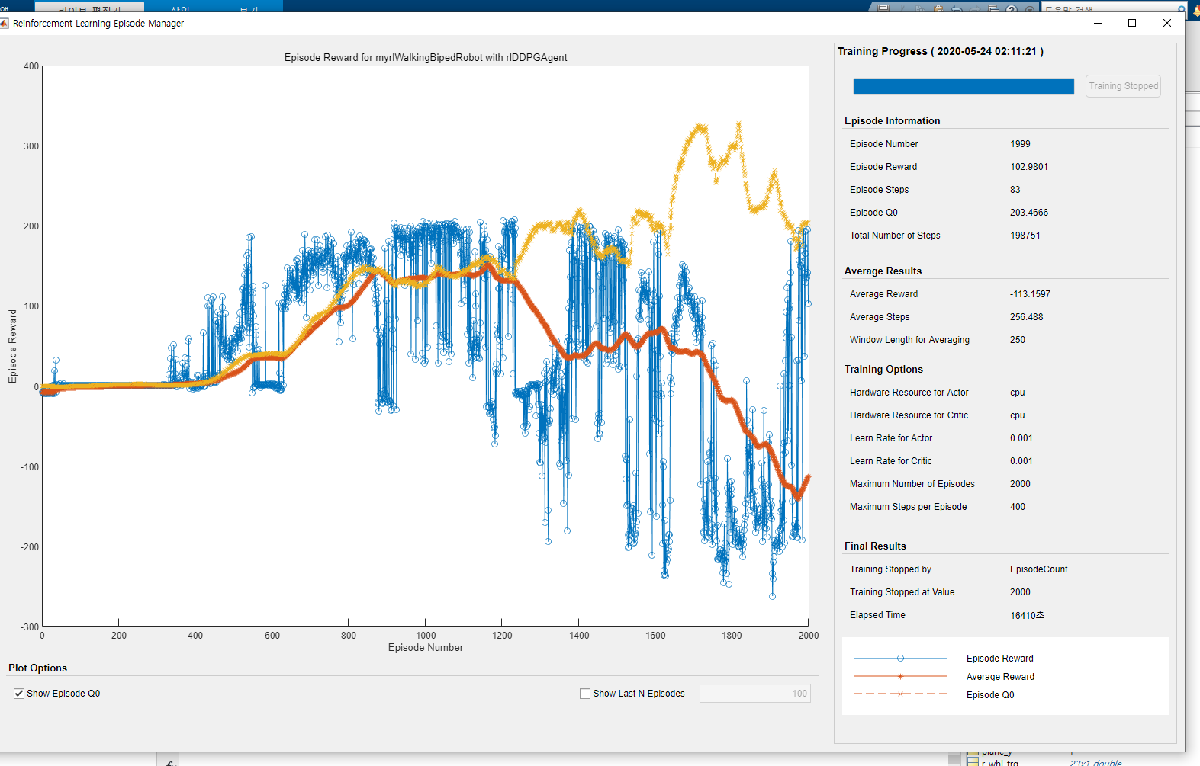

Load parameters of the model to the MATLAB® workspace.

% robotParametersRL
% load params_Robot_2_Whl.mat
load params_chkpt12.mat

Open the Simulink model.

mdl = 'BalancingRobot';
% open_system(mdl)

## **Create Environment Interface**

Create the observation specification.

% numObs = 29;
numObs = 15;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

Create the action specification.

numAct = 1;
actInfo = rlNumericSpec([numAct 1],'LowerLimit',-1,'UpperLimit',1);
actInfo.Name = 'wheel_torque';

Create the environment interface for the walking robot model.

blk = [mdl,'/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);
% env.ResetFcn = @(in) walkerResetFcn(in);

## Select and Create Agent for Training

This example provides the option to train the robot either using either a DDPG or TD3 agent. To simulate the robot with the agent of your choice, set the `AgentSelection` flag accordingly.

AgentSelection = 'DDPG';
switch AgentSelection
    case 'DDPG'
        agent = createDDPGAgent(numObs,obsInfo,numAct,actInfo,Ts);
    case 'TD3'
        agent = createTD3Agent(numObs,obsInfo,numAct,actInfo,Ts);
    otherwise
        disp('Enter DDPG or TD3 for AgentSelection')
end

## Specify Training Options and Train Agent

For this example, the training options for the DDPG and TD3 agents are the same. These options are based on the following requirements.

- Run each training session for 2000 episodes with each episode lasting at most `maxSteps` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option).

- Terminate the training only when it reaches the maximum number of episodes (`maxEpisodes`). Doing so allows the comparison of the learning curves for multiple agents over the entire training session. 

For more information and additional options, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxEpisodes = 2000;
maxSteps = floor(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',250,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeCount',...
    'StopTrainingValue',maxEpisodes,...
    'SaveAgentCriteria','EpisodeCount',...
    'SaveAgentValue',maxEpisodes);

Specify the following training options to train the agent in parallel training mode. If you do not have Parallel Computing Toolbox™ software installed, set `UseParallel` to `false`.

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- After every 32 steps, have each worker send experiences to the host. DDPG and TD3 agents require workers to send experiencesw to the host.

trainOpts.UseParallel = true;

trainOpts.ParallelizationOptions.Mode = 'async';
trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
trainOpts.ParallelizationOptions.DataToSendFromWorkers = 'Experiences';

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This process is computationally intensive and takes several hours to complete for each agent. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining `to `true`. Due to randomness in the parallel training, you can expect different training results from the plots below. The pretrained agents were trained in parallel using four workers.

doTraining = true;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the selected agent.
    if strcmp(AgentSelection,'DDPG')
       load('rlWalkingBipedRobotDDPG.mat','agent')
    else
       load('rlWalkingBipedRobotTD3.mat','agent')
    end  
end

## Simulate Trained Agents

Fix the random generator seed for reproducibility.

rng(0)

To validate the performance of the trained agent, simulate it within the biped robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions('MaxSteps',maxSteps);
experience = sim(env,agent,simOptions);

## References

[1] Heess, Nicolas, Dhruva TB, Srinivasan Sriram, Jay Lemmon, Josh Merel, Greg Wayne, Yuval Tassa, et al. ‘Emergence of Locomotion Behaviours in Rich Environments’. *ArXiv:1707.02286 [Cs]*, 10 July 2017. [https://arxiv.org/abs/1707.02286](https://arxiv.org/abs/1707.02286).

[2] Lillicrap, Timothy P., Jonathan J. Hunt, Alexander Pritzel, Nicolas Heess, Tom Erez, Yuval Tassa, David Silver, and Daan Wierstra. ‘Continuous Control with Deep Reinforcement Learning’. *ArXiv:1509.02971 [Cs, Stat]*, 5 July 2019. [https://arxiv.org/abs/1509.02971](https://arxiv.org/abs/1509.02971).

[3] Fujimoto, Scott, Herke van Hoof, and David Meger. ‘Addressing Function Approximation Error in Actor-Critic Methods’. *ArXiv:1802.09477 [Cs, Stat]*, 22 October 2018. [https://arxiv.org/abs/1802.09477](https://arxiv.org/abs/1802.09477).

*Copyright 2019 The MathWorks, Inc.*